%% A Konvolúciós Kódok Evolúciója: RSC Viterbi vs. LTE Turbo Kód
% Ez a szkript bemutatja, hogy a Turbo kód NEM egy hagyományos blokkkód,
% hanem valójában két egyszerű RSC (Konvolúciós) kódoló zseniális összekapcsolása!

clear; clc; close all;

% Paraméterek
dataLen = 1000;
EbNo_dB_array = 0:0.5:4; % Eb/No (Egy bitre jutó energia / Zaj)
max_keret = 200; % A Turbo dekódoló lassabb, így kevesebb keret is elég a demóhoz

% 1. Hagyományos Konvolúciós Kódoló (RSC) beállítása
% A 4G LTE alap kényszerhossza K=4 (8 állapotú trellis)
trellis = poly2trellis(4, [13 15], 13);
rate_viterbi = 1/2; % A sima RSC 1 bitből 2 kódolt bitet csinál

% 2. Turbo Kódoló beállítása
% Az LTE Turbo kód pontosan a fenti K=4-es RSC kódolót használja duplán!
intrlvIdx = randperm(dataLen).'; % Turbo Adatkeverő (Interleaver) - Oszlopvektor kell!
turboEnc = comm.TurboEncoder('TrellisStructure', trellis, 'InterleaverIndices', intrlvIdx);
% A 4 iteráció jelenti a dekódolók közötti "vitatkozások" számát
turboDec = comm.TurboDecoder('TrellisStructure', trellis, 'InterleaverIndices', intrlvIdx, 'NumIterations', 4);
rate_turbo = 1/3; % A Turbo kód 1 hasznos bitből 3 kódolt bitet csinál

% Eredménytárolók
ber_vit = zeros(size(EbNo_dB_array));
ber_turbo = zeros(size(EbNo_dB_array));

fprintf('--- Viterbi vs. Turbo Kód Szimuláció ---\n');

--- Viterbi vs. Turbo Kód Szimuláció ---



for idx = 1:length(EbNo_dB_array)
    ebno = EbNo_dB_array(idx);

    % Korrekt SNR számítás a különböző kódarányok (Rate) miatt
    % Így a két rendszer összehasonlítása (az egy bitre jutó energia alapján) igazságos lesz!
    snr_vit   = ebno + 10*log10(rate_viterbi);
    snr_turbo = ebno + 10*log10(rate_turbo);

    err_vit = 0; err_turbo = 0;

    % Zajvariancia az LLR (Log-Likelihood Ratio) pontos számításához
    nv_vit   = 10^(-snr_vit/10);
    nv_turbo = 10^(-snr_turbo/10);

    for k = 1:max_keret
        % Véletlen adat (Hasznos bitek)
        data = randi([0 1], dataLen, 1);

        %% --- 1. RENDSZER: Sima RSC + Viterbi ---
        enc_vit = convenc(data, trellis);

        % A matematikai BPSK konvenció (0 -> +1, 1 -> -1)
        tx_vit = 1 - 2 * enc_vit; 
        rx_vit = awgn(tx_vit, snr_vit, 'measured');

        % LLR számítás és Viterbi Dekódolás ('trunc' móddal)
        % A vitdec 'unquant' módja a POZITÍV LLR-t tekinti 0-nak!
        llr_vit = 2 * rx_vit / nv_vit;
        dec_vit = vitdec(llr_vit, trellis, 100, 'trunc', 'unquant');
        err_vit = err_vit + biterr(data, dec_vit);

        %% --- 2. RENDSZER: LTE Turbo Kód (Két RSC + Keverő) ---
        enc_turbo = turboEnc(data);

        % Ugyanaz a BPSK moduláció:
        tx_turbo = 1 - 2 * enc_turbo; 
        rx_turbo = awgn(tx_turbo, snr_turbo, 'measured');
        
        % A comm.TurboDecoder objektum a vitdec-kel ellentétben
        % a NEGATÍV LLR értékeket tekinti 0-s bitnek! 
        % Ha nem invertáljuk az LLR-t, majdnem 100%-os hibaarányt kapunk.
        llr_turbo = - (2 * rx_turbo) / nv_turbo; 

        dec_turbo = turboDec(llr_turbo);
        err_turbo = err_turbo + biterr(data, dec_turbo);
    end

    ber_vit(idx) = err_vit / (max_keret * dataLen);
    ber_turbo(idx) = err_turbo / (max_keret * dataLen);

    fprintf('Eb/No: %2.1f dB | Viterbi BER: %e | Turbo BER: %e\n', ...
        ebno, ber_vit(idx), ber_turbo(idx));


end

Eb/No: 0.0 dB | Viterbi BER: 2.508200e-01 | Turbo BER: 2.768300e-01
Eb/No: 0.5 dB | Viterbi BER: 2.336400e-01 | Turbo BER: 2.602800e-01
Eb/No: 1.0 dB | Viterbi BER: 2.096200e-01 | Turbo BER: 2.420400e-01
Eb/No: 1.5 dB | Viterbi BER: 1.840500e-01 | Turbo BER: 2.205600e-01
Eb/No: 2.0 dB | Viterbi BER: 1.491950e-01 | Turbo BER: 1.920250e-01
Eb/No: 2.5 dB | Viterbi BER: 1.209300e-01 | Turbo BER: 1.508950e-01
Eb/No: 3.0 dB | Viterbi BER: 9.163500e-02 | Turbo BER: 8.509500e-02
Eb/No: 3.5 dB | Viterbi BER: 6.461000e-02 | Turbo BER: 1.109500e-02
Eb/No: 4.0 dB | Viterbi BER: 4.373500e-02 | Turbo BER: 5.000000e-05


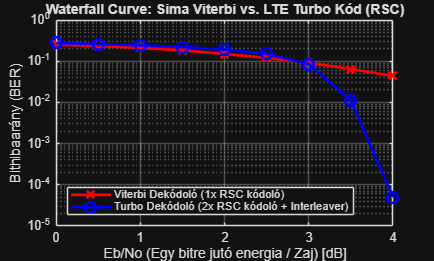


%% --- Eredmények kirajzolása ---
figure('Name', 'A Konvolúciós Kódok Evolúciója', 'NumberTitle', 'off');
semilogy(EbNo_dB_array, ber_vit, 'r-x', 'LineWidth', 2, 'MarkerSize', 8); hold on;
semilogy(EbNo_dB_array, ber_turbo, 'b-o', 'LineWidth', 2, 'MarkerSize', 8);
grid on;
title('Waterfall Curve: Sima Viterbi vs. LTE Turbo Kód (RSC)');
xlabel('Eb/No (Egy bitre jutó energia / Zaj) [dB]');
ylabel('Bithibaarány (BER)');
legend('Viterbi Dekódoló (1x RSC kódoló)', 'Turbo Dekódoló (2x RSC kódoló + Interleaver)', 'Location', 'southwest');